usage: teamwork for week 11

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.5.16

clear all; close all; clc

**1. 如果一个矩阵**$$A$$**是正定对称矩阵或是正定厄密矩阵， 那么它可以表达成**


$$   $$
   A = U^T U
   $$$$


**   其中**$$U$$**是一个上三角矩阵， 这样的分解称为Cholesky分解。 Matlab中`\`求解**$$Ax=b$$**时， 若**$$A$$**是正定对称(或正定厄密)矩阵， 则用下面的方法实现：**

**      - 先做Cholesky分解， 使得**$$A = U^T U$$**.**

**      - 然后求解**$$U^Ty=b$$**, 因为**$$U^T$$**是下三角矩阵， 可利用前向替代法求解**$$y$$**.**

**      - 最后求解**$$Ux=y$$**,  因为**$$U$$**是上三角矩阵， 可利用反向替代法求解**$$x$$**.**

**    请利用Matlab的内置函数`chol`进行Cholesky分解， 编写代码实现反向替代法和正向替代法，求解以下线性方程组：**


$$    $$
    \pmatrix {
    2 & 3 & 4\cr
    3 & 6 & 7\cr
    4 & 7 & 10}
    x=
    \pmatrix{
    2\cr
    4\cr
    8
 }
    $$$$


**    提示：若**$$A$$**不是对称矩阵， 仍可以采用Cholesky分解求解**$$(A^TA)x=A^Tb$$**.**

解：

clear all; close all; clc
A_1 = [2, 3, 4;...
       3, 6, 7;...
       4, 7, 10];
b_1 = [2; 4; 8];
x_1 = Cholesky_decomposition(A_1, b_1)

x_1 =    -2.5000
   -1.0000
    2.5000


**2. 参考样本程序， 编写代码， 同时实现雅可比迭代与高斯-赛德尔迭代， 并求解方程组**$$Ax=b$$**. 精度**$$\epsilon=0.5e-6$$**, 矩阵**$$A$$**定义为**

   
$$a_{ii}=-4\\
a_{ij}=2, 当|i-j|=1\\
a_{ij}=0, 当|i-j|\geq 2\\
 i,j=1,2,\cdots,10
$$


**   右端项**$$b$$**为：**

  
$$ $$
   b^T=[2\;3\;4\;\cdots\;11]
   $$$$


**   使用初始值**$$x_i=0$$**, 也可以使用其他初始值。 将结果与Matlab的`\`直接求得的结果进行对比。**

解：

首先生成A_2

clear all; close all; clc
% 构造A
A_2 = zeros(10);

A_2 =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


for i = 1:10
    for j = 1:10
        if i == j
            A_2(i, j) = -4;
        elseif abs(i - j) == 1
            A_2(i, j) = 2;
        else
            A_2(i, j) = 0;
        end
    end
end
b_2 = [2:11]';
% 以全零向量为初始值
x0_2 = zeros(length(b_2), 1);
% 分别用三种方法进行求解
[x_2_Jacobi, k_Jacobi, ~] = Jacobi(A_2, b_2, x0_2, 0.5e-6, 10000)

x_2_Jacobi =   -12.5000
  -24.0000
  -34.0000
  -42.0000
  -47.5000
  -50.0000
  -49.0000
  -44.0000
  -34.5000
  -20.0000


k_Jacobi = 390

[x_2_GaussSeide, k_GaussSeide, ~] = GaussSeidel(A_2, b_2, x0_2, 0.5e-6, 10000)

x_2_GaussSeide =   -12.5000
  -24.0000
  -34.0000
  -42.0000
  -47.5000
  -50.0000
  -49.0000
  -44.0000
  -34.5000
  -20.0000


k_GaussSeide = 205

x_2_backslash = A_2 \ b_2

x_2_backslash =   -12.5000
  -24.0000
  -34.0000
  -42.0000
  -47.5000
  -50.0000
  -49.0000
  -44.0000
  -34.5000
  -20.0000


可得雅可比迭代和高斯赛德尔迭代所得的结果与backslash完全相等，而雅可比迭代经过390次迭代得到结果，高斯赛德尔迭代经过205次迭代得到结果，可以看出高斯赛德尔迭代的收敛速度比雅可比迭代的收敛速度更快。

**3. 在求解**$$Ax=b$$**中， 可以把**$$A$$**表达成**$$A=V-U$$**, 这样**$$Vx=Ux+b$$**, 由此可以使用迭代公式**

$   $$
   Vx^{(k+1)}=Ux^{(k)}+b
   $$$**来求解。 **

**   现在取**$$V$**的主对角线上(diagonal)和上一行的副对角线上(upper diagonal)的矩阵元与**$$A$$**对应的矩阵元相同， 其余矩阵元为零.  采用与雅可比迭代法一样的迭代终止条件， 编写程序实现以上迭代方法， 并求解以下线性方程组**

    
$$$$
    \pmatrix{7 & 1 & -2 & 0 & 1\cr
    -1 & 6 & 1 & -2 & 1\cr
    0 & 2 & 8 & 3 & -2\cr
    2 & -1 & 4 & 10 & 2\cr
    1 & 3 & -1 & 5 & 12
    }x=
    \pmatrix{
    18 \cr
    0\cr
    -2\cr
    21\cr
    28}
    $$$$


**    初始试探值可取**


$$    $$
    x^{(0)}=\pmatrix{
    0 \cr
    0\cr
    0\cr
    1\cr
    0}
    $$$$


解：

clear all; close all; clc
A_3 = [7, 1, -2, 0, 1;...
       -1, 6, 1, -2, 1;...
       0, 2, 8, 3, -2;...
       2, -1, 4, 10, 2;...
       1, 3, -1, 5, 12];
b_3 = [18; 0; -2; 21; 28];
x0_3 = zeros(length(b_3), 1);
x0_3(4) = 1;
[x_3, k_3] = f3(A_3, b_3, x0_3, 0.5e-6, 10000)

x_3 =     2.0000
    1.0000
   -1.0000
    2.0000
    1.0000


k_3 = 38

x_3_check = A_3 \ b_3

x_3_check =     2.0000
    1.0000
   -1.0000
    2.0000
    1.0000


可以得到迭代方法得到的结果与backslash的结果完全相同。

**4. 正交矩阵**$$A$$**定义为矩阵与自身转置为单位矩阵的方阵， 即**


$$   $$
   AA^T=A^TA=I
   $$$$


**   请验证下列矩阵是正交矩阵**

   
$$
   P=\pmatrix{
   \frac{1}{\sqrt{3}}& \frac{1}{\sqrt{6}}& -\frac{1}{\sqrt{2}}\cr
   \frac{1}{\sqrt{3}}& -\frac{2}{\sqrt{6}}& 0\cr
   \frac{1}{\sqrt{3}}& \frac{1}{\sqrt{6}}& \frac{1}{\sqrt{2}}
   }\\
   Q = \pmatrix{
   \cos(\pi/3) & \sin(\pi/3)\cr
   -\sin(\pi/3) & \cos(\pi/3)
}$$


解：

clear all; close all; clc
% 验证P
P_4 = ones(3,3)./sqrt([3, 6, 2]);
P_4(2, 2) = P_4(2, 2) * (-2);
P_4(1, 3) = P_4(1, 3) * (-1);
P_4(2, 3) = 0;
fprintf("P=")

P=

disp(P_4)

    0.5774    0.4082   -0.7071
    0.5774   -0.8165         0
    0.5774    0.4082    0.7071



if isequal(round(P_4'*P_4, 4), eye(3,3))
    fprintf('P''P=I')
end

P'P=I

if isequal(round(P_4*P_4', 4), eye(3,3))
    fprintf('PP''=I')
end

PP'=I

% 验证Q
Q_4 = [cos(pi/3), sin(pi/3); -sin(pi/3), cos(pi/3)];
fprintf("Q=")

Q=

disp(Q_4)

    0.5000    0.8660
   -0.8660    0.5000



if isequal(round(Q_4'*Q_4, 4), eye(2,2))
    fprintf('Q''Q=I')
end

Q'Q=I

if isequal(round(Q_4*Q_4', 4), eye(2,2))
    fprintf('QQ''=I')
end

QQ'=I

**5. 利用`pinv`, `qr`, `\`求解如下超定方程组:**

  
$$
    \pmatrix{
    2.0 & -3.0 & 2.0 \cr
    1.9 & -3.0 & 2.2 \cr
    2.1 & -2.9 & 2.0 \cr
    6.1 & 2.1 & -3.0 \cr
    -3.0 & 5.0 & 2.1}
    \pmatrix{
    x_1 \cr x_2 \cr x_3}=\pmatrix{
    1.01\cr 1.01 \cr 0.98 \cr 4.94\cr 4.10}$$$$


解：

clear all; close all; clc
A_5 = [2.0, -3.0, 2.0;...
       1.9, -3.0, 2.2;...
       2.1, -2.9, 2.0;...
       6.1, 2.1, -3.0;...
       -3.0, 5.0, 2.1];
b_5 = [1.01; 1.01; 0.98; 4.94; 4.10];
% 利用伪逆求解
x_5_pinv = pinv(A_5)*b_5

x_5_pinv =     0.9500
    0.9811
    0.9727


% 利用QR分解
[Q_5, R_5, p_5] = qr(A_5, 0);
x_5_QR(p_5, :) = R_5\(Q_5\b_5)

x_5_QR =     0.9500
    0.9811
    0.9727


% 利用\
x_5_backslash = A_5 \ b_5

x_5_backslash =     0.9500
    0.9811
    0.9727


可以看到三种方法得到的结果相同。

**6. 以下数据是1900-2010年的美国总人口数，单位为百万人：**

**   | 年份 | 人口数 | 年份 | 人口数 |**

**   | 1900 | 75.995 | 1960 | 179.323|**

**   | 1910 | 91.972 | 1970 | 203.212 |**

**   | 1920 | 105.711 | 1980 | 226.505|**

**   | 1930 | 123.203 | 1990 | 249.633 |**

**   | 1940 | 131.669 | 2000 | 281.422 |**

**   | 1950 | 150.697 | 2010 | 308.748 | **

**   假设人口增长的模型是**$$t$$**的三次多项式， **

**   (1) 请采用QR分解法(Matlab内置的`qr`函数)， 实现最小二乘法，从而确定三次多项式中的4个参数， 并计算**$$\chi^2$$**.**

**   (2) 采用这个模型， 预测2020年的人口数。**

**   提示： **

**   (a) 先要对**$$t$$**做定标处理， 即采用变换**


$$    $$
    s = (t-1955)/55
    $$$$


**    则新变量**$$s$$**在**$$[-1,1]$$**区间内， 而模型为**


$$    $$
    y = a_0 + a_1 s + a_2 s^2 + a_3 s^3 
    $$$$


**    (b) 你可以选取缩小的样本， 比如6个数据`s=((1950:20:2000)'-1950)/50`, 做两阶多项式拟合**


$$    $$
    y = a_0 + a_1 s + a_2 s^2 
    $$$$


**    预测2010年的人口, 通过和实际人口普查数据的比较测试你的程序。**

解：

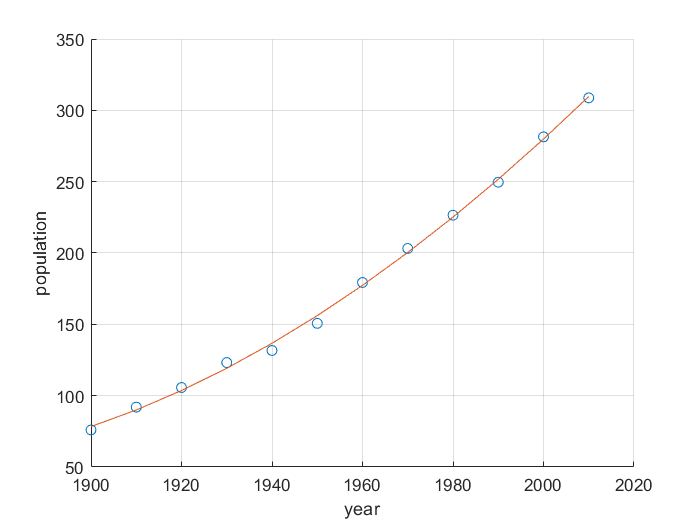

clear all; close all; clc
t_6 = 1900:10:2000;
t_6(12) = 2010;
y_6 = [75.995; 91.972; 105.711; 123.203; 131.669; 150.697;...
       179.323; 203.212; 226.505; 249.633; 281.422; 308.748];
scatter(t_6, y_6)
% 采用所有数据进行拟合

s_6_a = (t_6 - 1955)' / 55;
A_6_a = [ones(length(s_6_a), 1), s_6_a, s_6_a.^2, s_6_a.^3];
[Q_6_a, R_6_a, p_6_a] = qr(A_6_a, 0);
x_6_a(p_6_a, :) = R_6_a\(Q_6_a\y_6);
% 将参数带入三次多项式模型
f_6_a = @(x) [ones(length(x), 1), (x - 1955)/55, ((x - 1955)/55).^2, ((x - 1955)/55).^3]*x_6_a;
hold on
plot(t_6, f_6_a(t_6'))
hold off
grid on
xlabel("year")
ylabel("population")

% 计算卡方值
kaf = sum((f_6_a(t_6') - y_6).^2./y_6)

kaf = 0.7732

% 预测2020年的人口数
pred_2020 = f_6_a(2020)

pred_2020 = 341.1275

由$$\chi^2 = \sum\frac{(A-E)^2}{E}$，得到$$\chi^2=0.7732$，查表得计算得到的$$\chi^2$$已高于4自由度95%置信的卡方值，说明拟合优度非常好。

三次多项式拟合预测2020年美国人口数为341.1275百万人。

采用1900、1920、1940、...、2000年的数据进行拟合

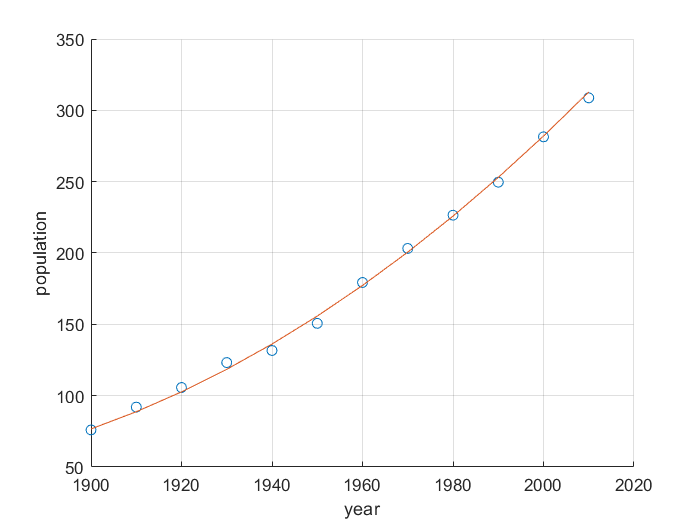

scatter(t_6, y_6)
% 采用部分数据进行拟合
s_6_b = ((1900:20:2000)' - 1955) / 55;
A_6_b = [ones(length(s_6_b), 1), s_6_b, s_6_b.^2];
[Q_6_b, R_6_b, p_6_b] = qr(A_6_b, 0);
x_6_b(p_6_b, :) = R_6_b\(Q_6_b\y_6(1:2:11));
% 将参数带入三次多项式模型
f_6_b = @(x) [ones(length(x), 1), (x - 1955)/55, ((x - 1955)/55).^2]*x_6_b;
hold on
plot(t_6, f_6_b(t_6'))
hold off
grid on
xlabel("year")
ylabel("population")

pred_2010 = f_6_b(2010)

pred_2010 = 312.8673

fprintf("用部分数据拟合的二阶多项式在2010年预测结果的误差为%.6f%%", abs(pred_2010 - y_6(end))/y_6(end)*100)

用部分数据拟合的二阶多项式在2010年预测结果的误差为1.334193%

************************************************functions******************************************

Cholesky_decomposition：

1)假如A是正定矩阵，则使用Cholesky分解为$$A = U^T U$$

2)假如A不是正定矩阵，则对$$(A^TA)x=A^Tb$$分解为$$A^TA = U^T U$$

然后求解$$U^Ty=b$$, 因为$$U^T$$是下三角矩阵， 可利用前向替代法求解$$y$$.

最后求解$$Ux=y$$,  因为$$U$$是上三角矩阵， 可利用反向替代法求解$$x$$.

args：

    A，b

output：

    x

function x = Cholesky_decomposition(A, b)
    try chol(A);% 检测A是否为正定矩阵
        U = chol(A); % 若是正定矩阵则直接求解U
    catch ME
        U = chol(A'*A); % 若不是正定矩阵则方程两边同乘A'
        b = A'*b;
    end
    % 初始化
    UT = U';
    n = length(b);
    y = zeros(n, 1);
    y(1) = b(1)/UT(1, 1);
    % 前向替代法
    for i = 2:n
        y(i) = (b(i) - UT(i,1:i-1)*y(1:i-1))/UT(i, i);
    end
    % 后向替代法
    x = zeros(n, 1);
    x(n) = y(n)/U(n, n);
    for i = n-1:-1:1
        x(i) = (y(i)-U(i,i+1:n)*x(i+1:n))/U(i,i);
    end
end

Jacobi：雅可比迭代求解线性方程组

function [x, k, Jnorm] = Jacobi(A, b, x0, tol, kmax)
%
% Jacobi uses the Jacobi iteration method to approximate
% the solution of Ax = b.
%
% [x, k, MJnorm] = Jacobi(A, b, x0, tol, kmax) where
%
% A is the n-by-n coefficient matrix,
% b is the n-by-1 right-hand side vector,
% x0 is the n-by-1 initial vector (default zeros),
% tol is the scalar tolerance for convergence (default 1e-4),
% kmax is the maximum number of iterations (default 100),
%
% x is the n-by-1 solution vector,
% k is the number of iterations required for convergence,
% MJnorm is the infinite norm of the Jacobi iteration
% matrix.
% Esfandiari Ramin, Numerical Methods for Engineers and Scientists using
% Matlab
% Section 4.5, p.130

if nargin < 3 || isempty(x0)
    x0 = zeros(size(b));
end
if nargin < 4 || isempty(tol)
    tol = 1e-4;
end
if nargin < 5 || isempty(kmax)
    kmax = 100;
end

x(:, 1) = x0;

D = diag(diag(A)); At = A - D;
L = tril(At);
U = triu(At);

% Norm of Jacobi iteration matrix
P = D\b;
Q = -D\(L + U); Jnorm = norm(Q, inf);


% Perform iterations up to kmax
for k = 1:kmax
    x(:, k+1) = P + Q*x(:, k) ; % Compute next approximation
    if norm(x(:, k+1) - x(:, k)) < tol, break; end    % Check convergence
end
x = x(:, end);
end

GaussSeidel：高斯赛德尔迭代求解线性方程组

function [x, k, GSnorm] = GaussSeidel(A, b, x0, tol, kmax)
%
% Jacobi uses the Gauss-Seidel iteration method to approximate
% the solution of Ax = b.
%
% [x, k, GSnorm] = GaussSeidel(A, b, x0, tol, kmax) where
%
% A is the n-by-n coefficient matrix,
% b is the n-by-1 right-hand side vector,
% x0 is the n-by-1 initial vector (default zeros),
% tol is the scalar tolerance for convergence (default 1e-4),
% kmax is the maximum number of iterations (default 100),
%
% x is the n-by-1 solution vector,
% k is the number of iterations required for convergence,
% GSnorm is the infinite norm of the Gauss-Seidel iteration
% matrix.
% Esfandiari Ramin, Numerical Methods for Engineers and Scientists using
% Matlab
% Section 4.5, p.132

if nargin < 3 || isempty(x0)
    x0 = zeros(size(b));
end
if nargin < 4 || isempty(tol)
    tol = 1e-4;
end
if nargin < 5 || isempty(kmax)
    kmax = 100;
end

x(:, 1) = x0;
D = diag(diag(A)); At = A - D;
L = tril(At);
U = triu(At);

% Norm of Jacobi iteration matrix
P = (D+L)\b;
Q = -(D+L)\U ; GSnorm = norm(Q, inf);

% Perform iterations up to kmax
for k = 1:kmax
    x(:, k+1) = P + Q*x(:, k) ; % Compute next approximation
    %disp(x(:,k+1));
    if norm(x(:, k+1) - x(:, k)) < tol, break; end    % Check convergence
end
x = x(:, end);
end

f3： 在求解$$Ax=b$$中， 可以把$$A$$表达成$$A=V-U$$, 这样$$Vx=Ux+b$$, 由此可以使用迭代公式$   $$
   Vx^{(k+1)}=Ux^{(k)}+b
   $$$来求解

args：

    A，b

    x0：初始值

    tol：误差上限

    kmax：最大迭代次数

output：

    x：求得的解

    k：迭代次数

function [x, k] = f3(A, b, x0, tol, kmax)
    % 设置缺省值
    if nargin < 3 || isempty(x0)
        x0 = zeros(size(b));
    end
    if nargin < 4 || isempty(tol)
        tol = 1e-4;
    end
    if nargin < 5 || isempty(kmax)
        kmax = 100;
    end
    x(:, 1) = x0;
    V = diag(diag(A)) + diag(diag(A, 1), 1);
    U = V - A;
    
    for k = 1:kmax
        x(:, k+1) = V \ (U*x(:, k) + b);
        if norm(x(:, k+1) - x(:, k)) < tol, break; end
    end
    x = x(:, end);
    
end